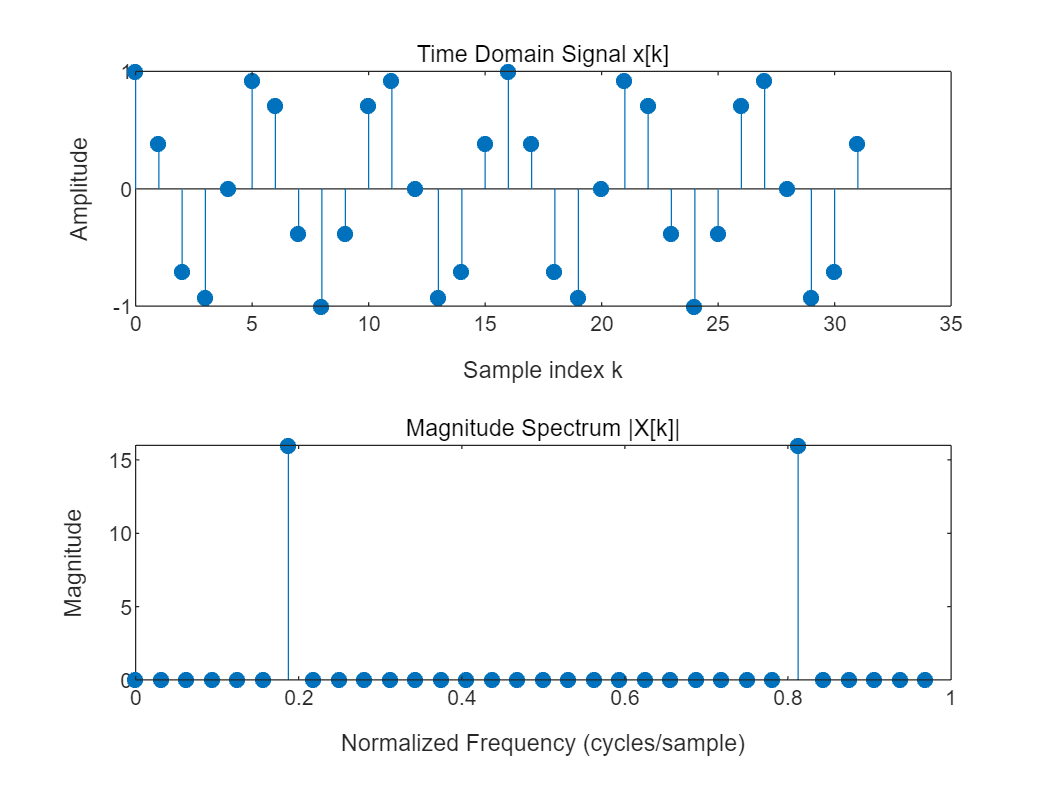

% LAB 2.2.1 刘兴琰 AI1 202264690069

N = 32; 
k = 0:N-1; 
x_k = cos(3*pi*k/8);

X_k = fft(x_k, N);

frequency_bins = (0:N-1)/N;

theoretical_bin_positive = 3*N/8; 
theoretical_bin_negative = N - theoretical_bin_positive; 
theoretical_magnitude = N/2; 

magnitude_spectrum = abs(X_k);

[calculated_magnitude_positive, calculated_bin_positive] = max(magnitude_spectrum(1:N/2));
[calculated_magnitude_negative, calculated_bin_negative] = max(magnitude_spectrum(N/2+1:end));

calculated_bin_negative = calculated_bin_negative + N/2;

error_magnitude_positive = abs(theoretical_magnitude - calculated_magnitude_positive);
error_magnitude_negative = abs(theoretical_magnitude - calculated_magnitude_negative);

figure;
subplot(2,1,1);
stem(k, x_k, 'filled');
title('Time Domain Signal x[k]');
xlabel('Sample index k');
ylabel('Amplitude');

subplot(2,1,2);
stem(frequency_bins, magnitude_spectrum, 'filled');
title('Magnitude Spectrum |X[k]|');
xlabel('Normalized Frequency (cycles/sample)');
ylabel('Magnitude');
xlim([0 1]); 

disp('Theoretical and Calculated Values:');

Theoretical and Calculated Values:


disp(['Theoretical Bin (Positive Frequency): ', num2str(theoretical_bin_positive)]);

Theoretical Bin (Positive Frequency): 12


disp(['Calculated Bin (Positive Frequency): ', num2str(calculated_bin_positive)]);

Calculated Bin (Positive Frequency): 7


disp(['Theoretical Bin (Negative Frequency): ', num2str(theoretical_bin_negative)]);

Theoretical Bin (Negative Frequency): 20


disp(['Calculated Bin (Negative Frequency): ', num2str(calculated_bin_negative)]);

Calculated Bin (Negative Frequency): 27


disp(['Theoretical Magnitude: ', num2str(theoretical_magnitude)]);

Theoretical Magnitude: 16


disp(['Calculated Magnitude (Positive Frequency): ', num2str(calculated_magnitude_positive)]);

Calculated Magnitude (Positive Frequency): 16


disp(['Calculated Magnitude (Negative Frequency): ', num2str(calculated_magnitude_negative)]);

Calculated Magnitude (Negative Frequency): 16


disp(['Error in Magnitude (Positive Frequency): ', num2str(error_magnitude_positive)]);

Error in Magnitude (Positive Frequency): 1.7764e-15


disp(['Error in Magnitude (Negative Frequency): ', num2str(error_magnitude_negative)]);

Error in Magnitude (Negative Frequency): 1.7764e-15


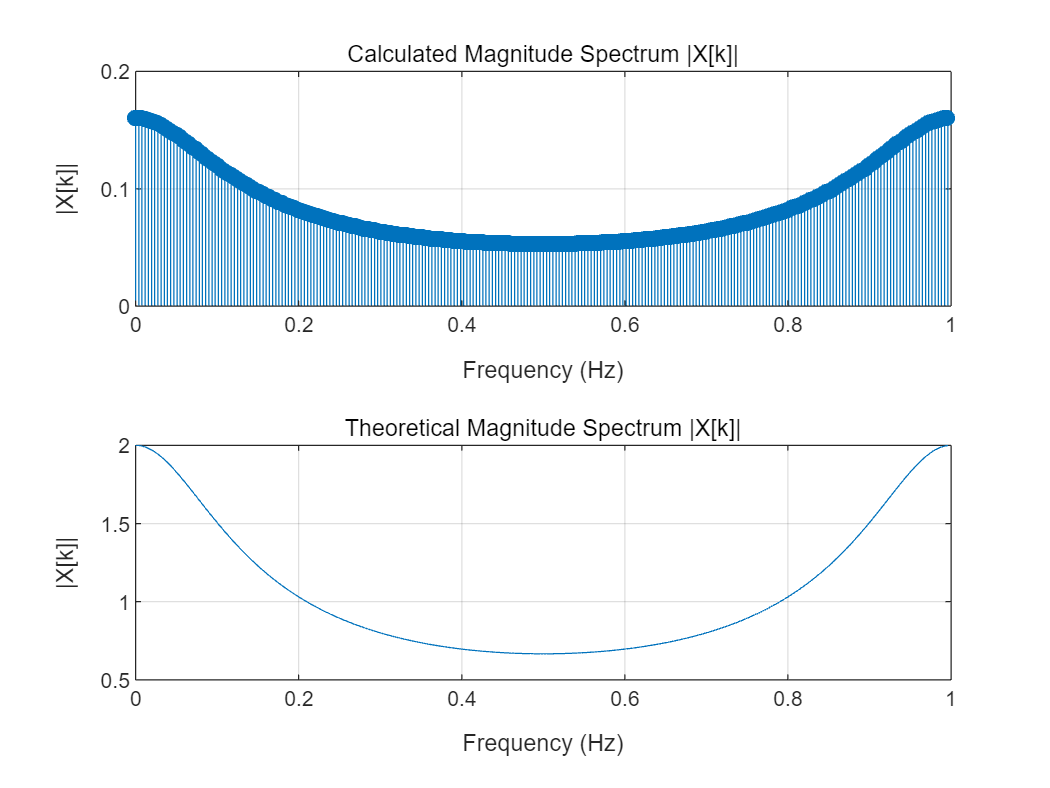

% LAB 2.2.2 刘兴琰 AI1 202264690069

N = 256; 
Fs = 1; 

k = 0:N-1; 

x_k = (1/2).^k;

window = hamming(N)'; 
x_k_windowed = x_k .* window;

X_k_windowed = fft(x_k_windowed, N);

frequency_bins = (0:N-1) * (Fs/N);

theoretical_spectrum = 1 ./ (1 - (1/2) * exp(-1j * 2 * pi * frequency_bins));

magnitude_spectrum = abs(X_k_windowed);

figure;
subplot(2,1,1);
stem(frequency_bins, magnitude_spectrum, 'filled');
title('Calculated Magnitude Spectrum |X[k]|');
xlabel('Frequency (Hz)');
ylabel('|X[k]|');
grid on;

subplot(2,1,2);
plot(frequency_bins, abs(theoretical_spectrum));
title('Theoretical Magnitude Spectrum |X[k]|');
xlabel('Frequency (Hz)');
ylabel('|X[k]|');
grid on;

disp('Comparison between theoretical and calculated magnitude spectrum values:');

Comparison between theoretical and calculated magnitude spectrum values:


disp(['Maximum calculated magnitude: ', num2str(max(magnitude_spectrum))]);

Maximum calculated magnitude: 0.16084


disp(['Maximum theoretical magnitude: ', num2str(max(abs(theoretical_spectrum)))]);

Maximum theoretical magnitude: 2


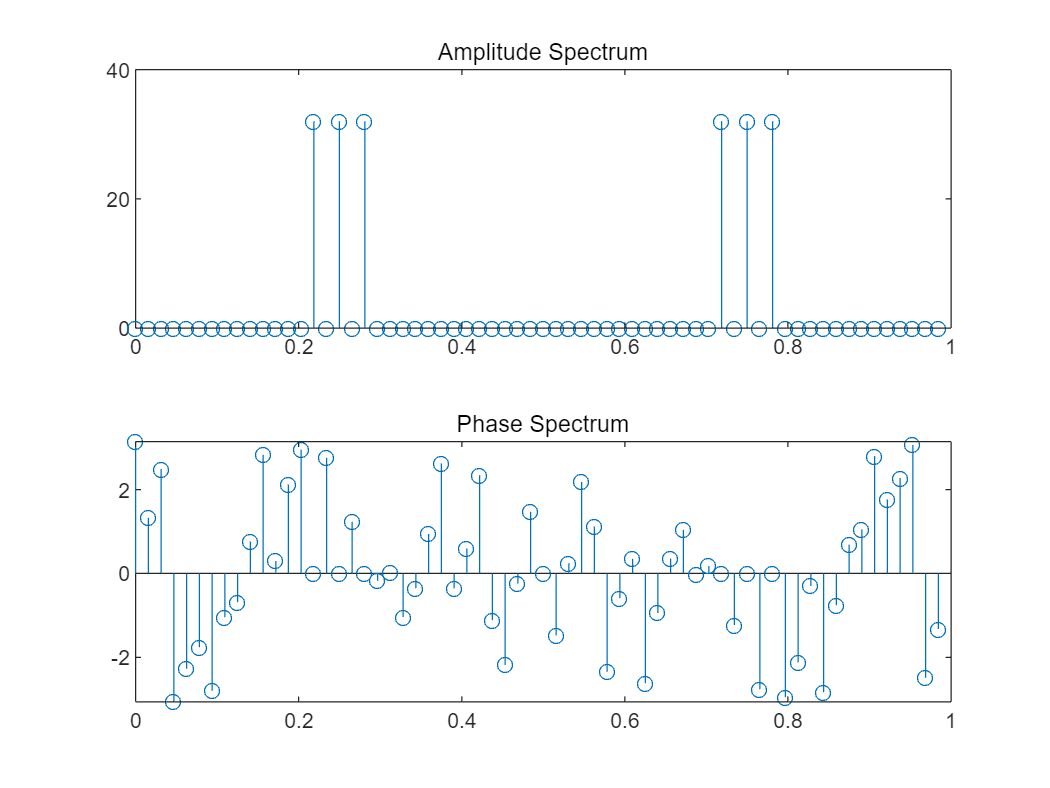

% Errors in the signal spectrum analysis could be due to:
% - The window function, which alters the original signal.
% - Numerical errors inherent in the FFT algorithm.
% - Truncation of the signal to N samples, which might not capture all significant components.

% Potential improvements include:
% - Increasing the length N to capture more of the signal.
% - Using a different window function that better preserves the signal characteristics.
% - Performing the analysis with higher precision arithmetic if numerical errors are significant.


% LAB 2.2.3 刘兴琰 AI1 202264690069
x_k = [2,3,3,1,0,5];
X_k = fft(x_k);

amplitude_spectrum = abs(X_k);
phase_spectrum = unwrap(angle(X_k));

N = length(x_k);
frequency_bins = (0:N-1)/N;

figure;
subplot(2,1,1);
stem(frequency_bins, amplitude_spectrum, 'filled');
title('Amplitude Spectrum');
xlabel('Normalized Frequency (cycles/sample)');
ylabel('Amplitude');

subplot(2,1,2);
stem(frequency_bins, phase_spectrum, 'filled');
title('Phase Spectrum');
xlabel('Normalized Frequency (cycles/sample)');
ylabel('Phase (radians)');

grid on;